FluoColonyImageRecognition

Shuai Yang 2021.03.29

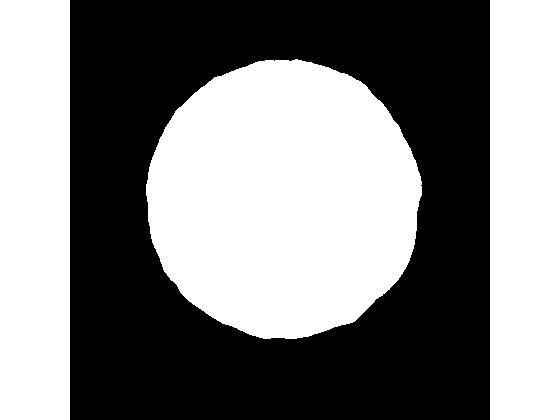

image = imagesfGFP00001;
I0 = substractBackGround(image);

I0 = imgaussfilt(I0,2);
I0 = rescale(double(I0))*255;
I0 = uint8(I0);

gaussianFilter = fspecial('gaussian',[10, 10], 3);% suitable for fluo images
edgeFilter = (ones(5,5)).*-1; edgeFilter(3,3) = 24;  %here create edgeFilter

I1 = I0;

thresh = imageThresholdGet(I1,'Otsu');
thresh = thresh/1.3;% default equals to 2
I2 = imbinarize(I1,thresh);
imshow(I2);

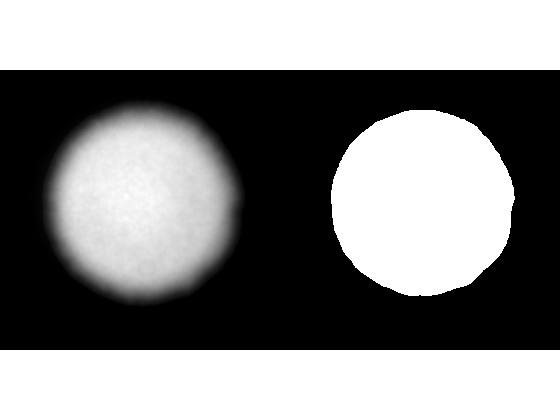

imshowpair(I0,I2,'montage')

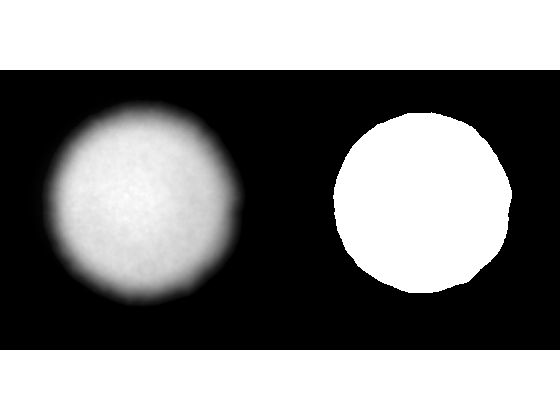

se = strel('disk',20);
I3 = imerode(I2,se);
imshowpair(I0,I3,'montage')

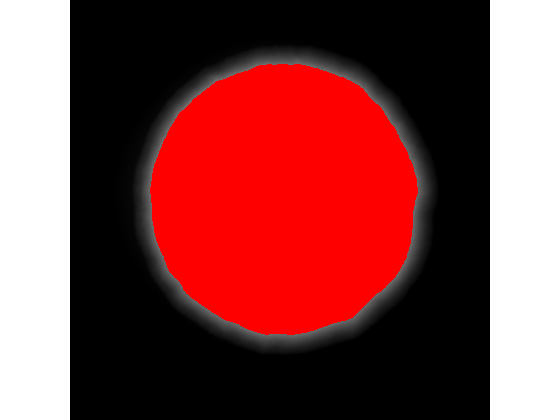

imshow(imoverlay(uint8(rescale(double(I0))*255),I3,[1,0,0]));

function I = substractBackGround(I)
%% subfunction
%用于减除图像的背景 Shuai Yang 2020.09.09
sz = size(I);
I0 = I(round(sz(1)/2-sz(1)/4):round(sz(1)/2+sz(1)/4),round(sz(2)/2-sz(2)/4):round(sz(2)/2+sz(2)/4));
I0 = double(I0);
I0 = sort(I0(:));
pixelSpace = 1:100:numel(I0);%每100个pixel计算平均值
M = zeros(numel(pixelSpace)-1,1);
for i = 1:numel(pixelSpace)-1
    M(i) = mean(I0(pixelSpace(i):pixelSpace(i+1)));
end

n = 5;
CV = std(M(1:n))/mean(M(1:n));
while CV > 0.03 % equal CV > 0.03 && n >= 1
    n = n-1;
    CV = std(M(1:n))/mean(M(1:n));
end
BG = mean(M(1:n));
I = I - BG;
end

function  T = imageThresholdGet(I,Method)
%I: 8bit image
%method 'Iterative','Otsu'
if nargin<2 || isempty(Method)
    Method = 'Otsu';
end

if strcmp(Method,'Otsu')
    T = graythresh(im2double(I));
end

if strcmp(Method,'Iterative')
    f = im2double(I);
    T = 0.5*(min(f(:))+max(f(:)));
    done=false;
    while ~done
        g = f>=T;
        Tn = 0.5*(mean(f(g))+mean(f(~g)));
        done = abs(T-Tn)<0.1;
        T = Tn;
    end
    T = T/255;
end
end